# Data Manipulation Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 16/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Prepared data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

**Set Directories & Load Data**

Load Signal data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

% rename the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_TableFilled.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

## 2. ASSET Data Manipulation

### 2.1 **Normalize ** the TRI series to have the first index value of each asset equal to 1. 

This creates a comparative wealth series for each asset over the time period.

% Divide each element in each column of x by the first element of that column
ASSETCL_normalised_array = table2array(ASSETCL_TableFilled) ./ table2array(repmat(ASSETCL_TableFilled(1,:),height(ASSETCL_TableFilled),1));

% Convert the normalised array back to a timetable with the same timestamps as x
ASSETCL_normalised = array2timetable(ASSETCL_normalised_array, 'RowTimes', ASSETCL_TableFilled.Time);

% Copy the column names from x to x_normalised
ASSETCL_normalised.Properties.VariableNames = ASSETCL_TableFilled.Properties.VariableNames;

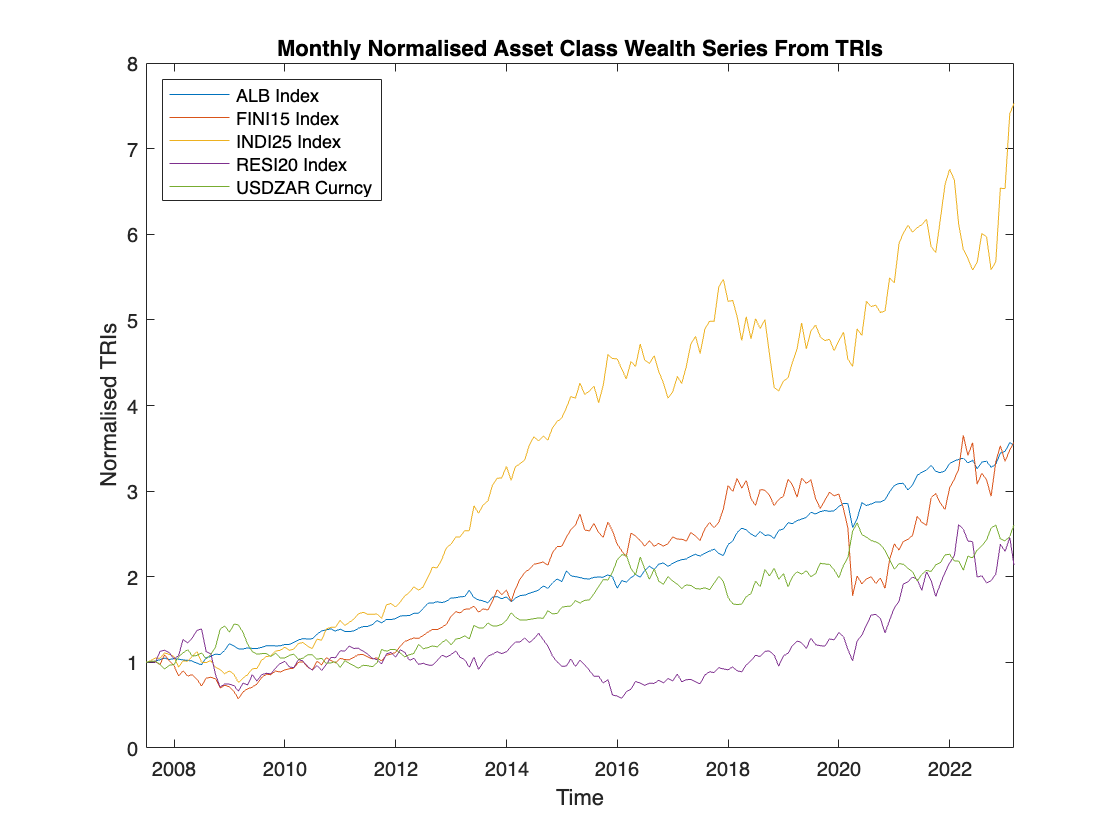

assetnames = ASSETCL_normalised.Properties.VariableNames;
% Plot all asset normalised TRIs on a single plot
plot(ASSETCL_normalised.Time, table2array(ASSETCL_normalised));
ylabel("Normalised TRIs");
xlabel("Time");
title("Monthly Normalised Asset Class Wealth Series From TRIs");
% include the legend
legend(ASSETCL_PlotNames,Location="northwest");
ASSETCL_norm_plot = gca;
hold off;

**Export Normalized Asset Class Wealth Series From TRIs Data plot**

exportName = 'ASSETCL_norm_plot.pdf';
exportgraphics(ASSETCL_norm_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 2.2 Calculate the Log Prices Series

% Log all columns of x and return as a new timetable object
lg_ASSETCL = varfun(@(ASSETCL_normalised) log(ASSETCL_normalised), ASSETCL_normalised, ...
    'OutputFormat', 'timetable');

% Copy the metadata from ASSETCL_normalised to lg_ASSETCL
lg_ASSETCL.Properties.Description = ASSETCL_normalised.Properties.Description;
lg_ASSETCL.Properties.VariableDescriptions = ASSETCL_normalised.Properties.VariableDescriptions;
lg_ASSETCL.Properties.VariableNames = ASSETCL_normalised.Properties.VariableNames;

% Plot all asset log(normalised TRIs) on a single plot
plot(lg_ASSETCL.Time, table2array(lg_ASSETCL));
ylabel("log(price)");
xlabel("Time");
title("Monthly Log Prices Series of Asset Class");
% include the legend
legend(ASSETCL_PlotNames,Location="northwest");
ASSETCL_logP_plot = gca;
hold off

**Export Log Price Plot**

exportName = 'ASSETCL_logP_plot.pdf';
exportgraphics(ASSETCL_logP_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 2.3 Calculating Log Price Differencing to first order of all Asset Classes  (create fn later)

% Calculate the log differences of all columns
ASSETCL_array = table2array(ASSETCL_TableFilled);
ASSETCL_log_array = log(ASSETCL_array);
ASSETCL_log_diff_array = diff(ASSETCL_log_array);

% Create a new timetable object with the log differences
ASSETCL_log_diff = array2timetable(ASSETCL_log_diff_array, 'RowTimes', ASSETCL_TableFilled.Time(2:end));

% Copy the metadata from ASSETCL_TableFilled to ASSETCL_log_diff
ASSETCL_log_diff.Properties.Description = ASSETCL_TableFilled.Properties.Description;
ASSETCL_log_diff.Properties.VariableDescriptions = ASSETCL_TableFilled.Properties.VariableDescriptions;
ASSETCL_log_diff.Properties.VariableNames = ASSETCL_TableFilled.Properties.VariableNames;

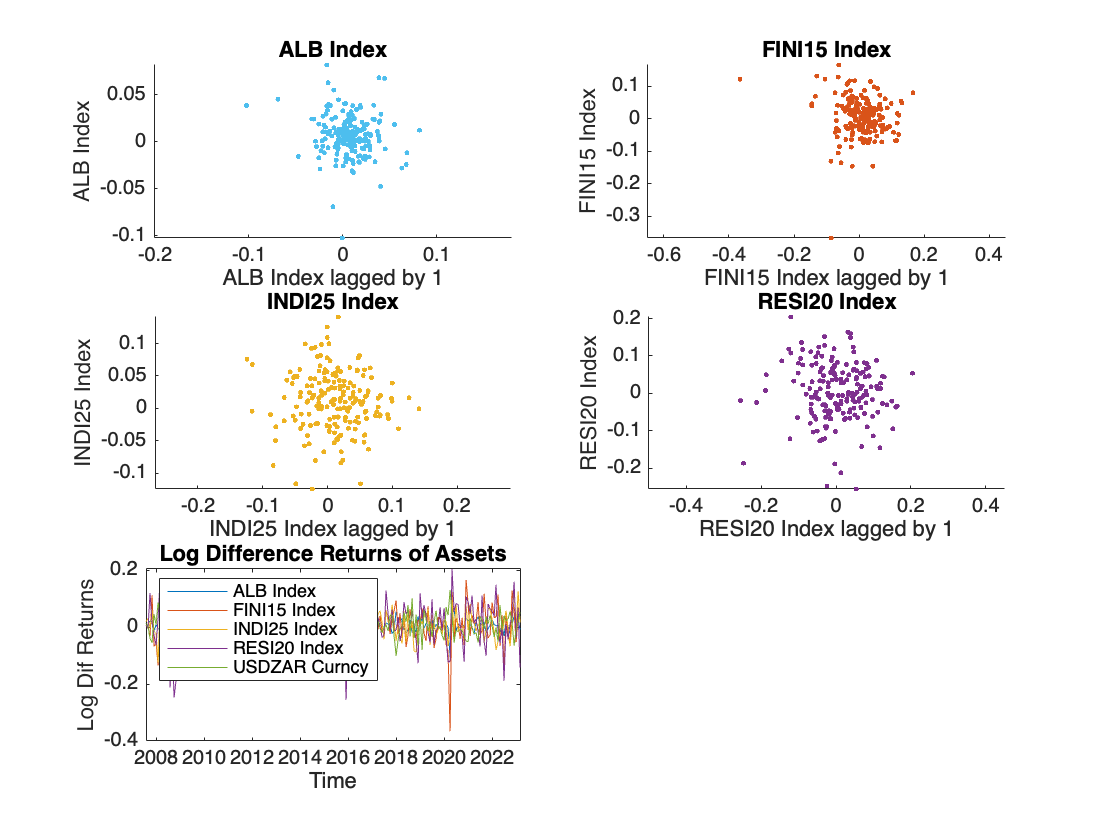

% Plot all asset log(normalised TRIs) on a single plot
plot(ASSETCL_log_diff.Time, table2array(ASSETCL_log_diff))
ylabel("Log Dif Returns")
xlabel("Time")
title("Monthly Log Difference Returns of Assets")
% include the legend
legend(ASSETCL_PlotNames,Location="northwest");
ASSETCL_logDifRet_plot = gca;
hold off;

#### **Export Log Diff Returns Plot**

exportName = 'ASSETCL_logDifRet_plot.pdf';
exportgraphics(ASSETCL_logDifRet_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### **SAVE Log Diff Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**

% % Convert the start and end dates to strings in the desired format (YYYYMMDD)
% startDateStr = datestr(ASSETCL_log_diff.Properties.StartTime, 'yyyymmdd');
% endDateStr = datestr(ASSETCL_log_diff.Properties.EndDate, 'yyyymmdd');
% 
% % Generate the file name
% fileName = sprintf('DATA-PROCESSED-INVARIANT-LOGDIFRETURNS-M-TTABLE-%s-%s.mat', startDateStr, endDateStr);
% 
% % Save the timetable object using the generated file name
% % save(fileName, 'timetableObj');

% 
exportName = 'DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat';
save(fullfile(dataExportpath,exportName),'ASSETCL_log_diff');

### 2.4 Check for normal distribution of returns 

Plot PP and QQ-plots to see if log diff data is roughly normally distributed

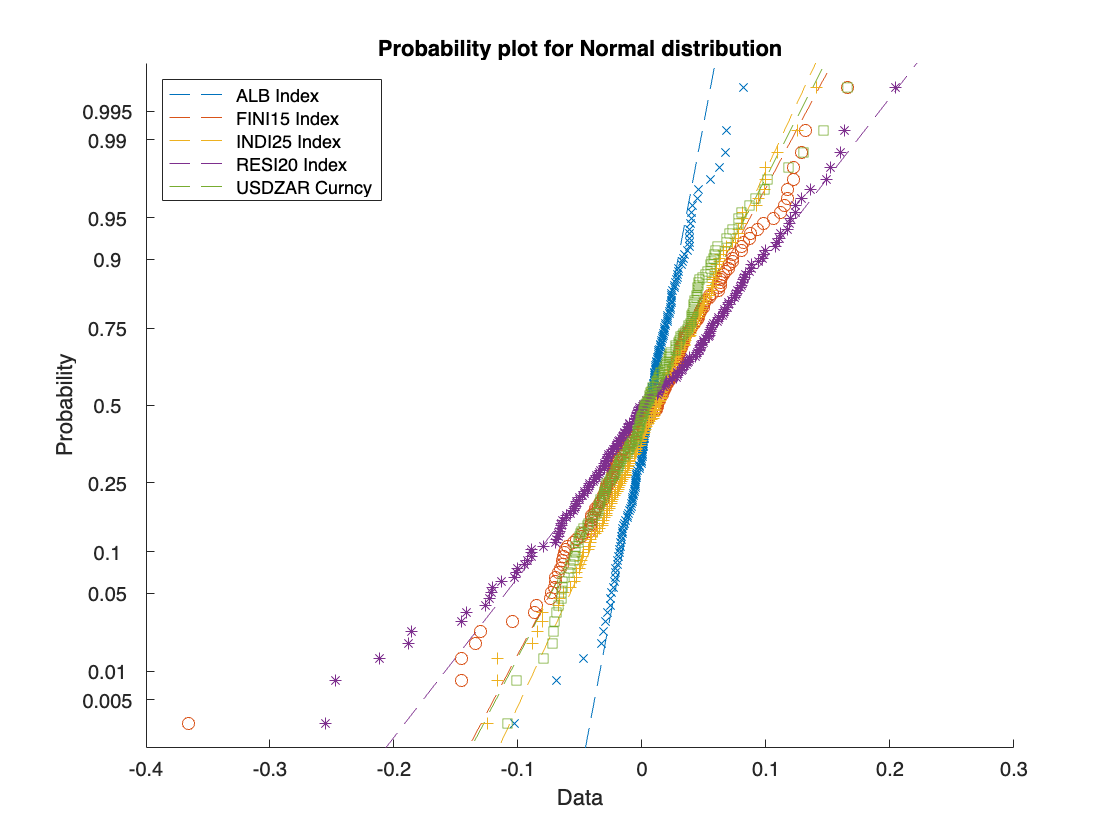

probplot(table2array(ASSETCL_log_diff));
legend(ASSETCL_PlotNames,Location="northwest");
ASSETCL_logDifRet_PP_plot = gca;
hold off;

**Export PP plot of ASSET Class log diff returns**

exportName = 'ASSETCL_logDifRet_PP_plot.pdf';
exportgraphics(ASSETCL_logDifRet_PP_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

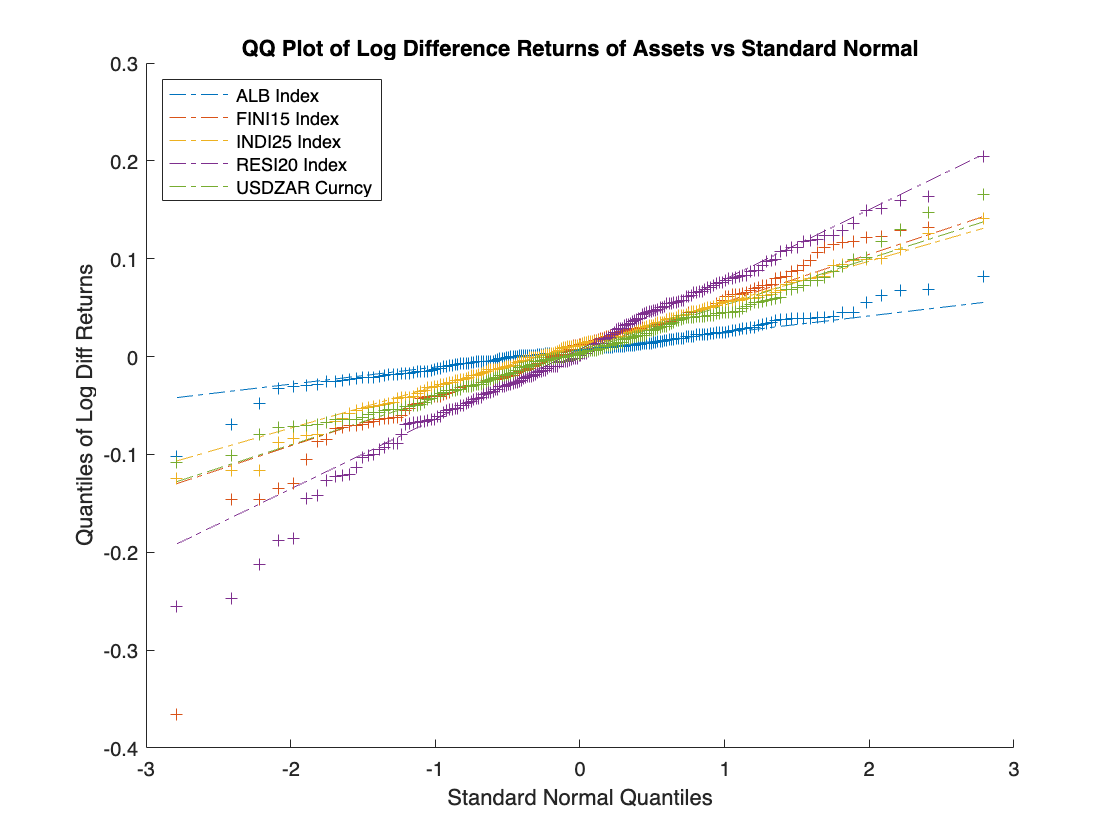

qqplot(table2array(ASSETCL_log_diff));
ylabel("Quantiles of Log Diff Returns")

title("QQ Plot of Log Difference Returns of Assets vs Standard Normal")
legend(ASSETCL_PlotNames,Location="northwest");
ASSETCL_logDifRet_QQ_plot = gca;
hold off;

**Export QQ plot of ASSET Class log diff returns**

exportName = 'ASSETCL_logDifRet_QQ_plot.pdf';
exportgraphics(ASSETCL_logDifRet_QQ_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 2.5 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

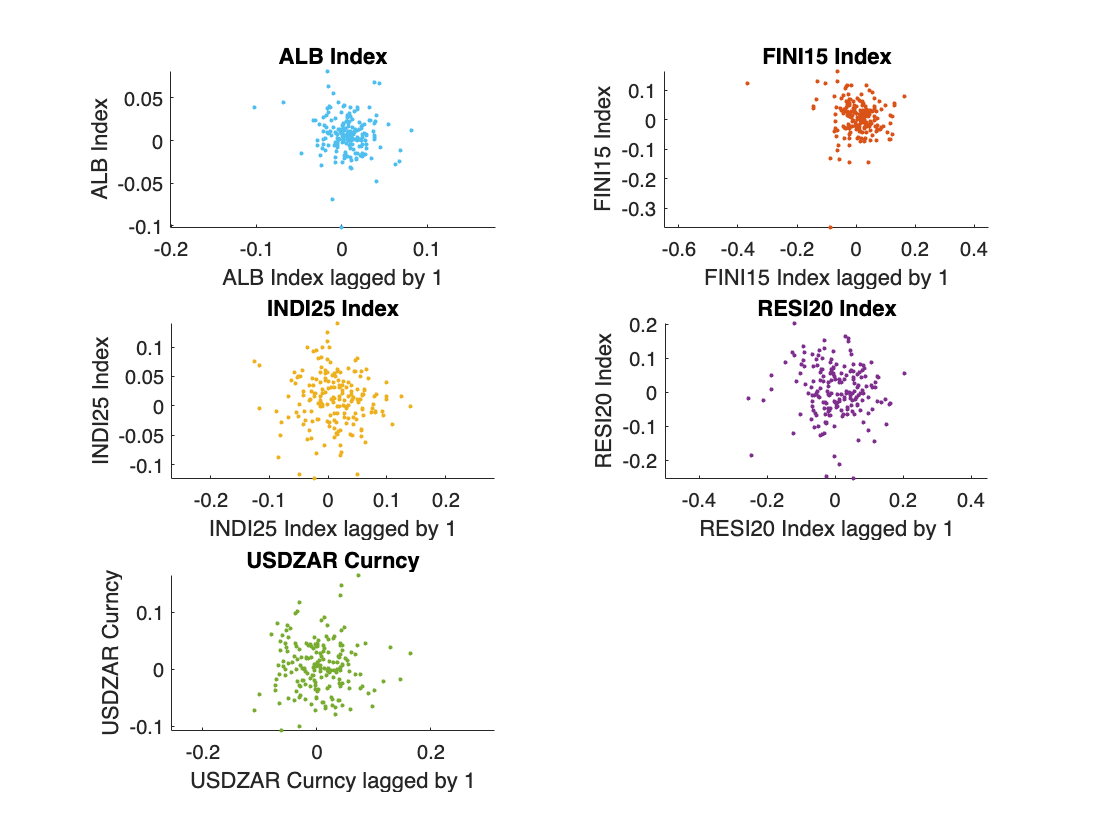

% Get the variable names 
varNames = ASSETCL_log_diff.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 3;
numCols = 2;

% Colour palette: Hexadecimal Colour Codes
colours = [0.3010 0.7450 0.9330; % blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880]; % green

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = ASSETCL_log_diff.(varNames{i});
    current_lag = lagmatrix(current_var, 1);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colours(i,:));
    
    % Set the title & axis labels of subplots
    title(ASSETCL_PlotNames{i});
    ylabel(ASSETCL_PlotNames{i});
    xlabel(strcat(ASSETCL_PlotNames{i}, " lagged by 1"));

    % Make the x, y axes equal in length
    axis equal;
end

% Export the fig as a PDF
ASSETCL_logDifRet_Lag_Scatterplot = gcf;
hold off

**Export log dif returns against its lag plot of ASSET **

exportName = 'ASSETCL_logDifRet_Lag_Scatterplot.pdf';
exportgraphics(ASSETCL_logDifRet_Lag_Scatterplot,fullfile(imageExportpath,exportName),'Resolution',300);

- We need **risk drivers** to be **homogenous** over time but don't need to be iid.

- **Invariants** need to be **iid** across time, *however, * weaker assumption of **ergodicity** will suffice (and check stationarity)

*"If the idea is that one wants to predict the trend of the time series into the future using extrapolation of the historical time series, the time series needs to be stationary and ergodic." - From proposal *

Condition a.) of risk drivers 'the risk driver Y_t needs to completely specify the security price at any given time along with the security t&cs. However, if we have Stock prices (p) we know that prices are non-homogenous e.g. in the fixed income field, prices converge to the face value of zero coupon bonds as maturity approaches.

**Test for 1-2:**

**1. Test for homogeneity**

see: https://www.xlstat.com/en/solutions/features/homogeneity-tests-for-time-series#:~:text=What%20are%20homogeneity%20tests%20for,at%20which%20a%20change%20occurs.

**2. Test for iid, ergodicity and stationarity: **

IID: Scatter plot of compound returns log(S_t+1/ S_t) if is circular the variable will be a candidate for an invariant. 

Ergodicity: 

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

Therefore we need to adapt P to satisfy condition a.). The log price series is homogenous 

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

adftest(SIG_aligned_dataTable2lag.("JALSHTR Index"))

plot(SIG_aligned_dataTable2lag.("JALSHTR Index"));
title('Simulated Time Series')
xlabel('t')
ylabel('ALSITR')
close all

subplot(2,1,1)
autocorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
subplot(2,1,2)
parcorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
close all

********************** Spelling checked to here. *******************